## Initial Conditions

clf;
clear;

### Environmental Variables

% Constants
ms_to_kn = 1.94384;
rho_air = 1.225; % air density [kg/m3]
mu_air = 1.81*10^(-5); % kinematic Viscosity [m^2/s]
rho_water = 1020; % water density [kg/m3]
mu_water = 1.04*10^(-6); % kinematic Viscosity [m^2/s]

% Globally changing
W_speed = 0.01; % wind speed [m/s]
W_angle = 0.01; % [rad] wind angle relative to bow, (+ve to the right)

% Extra variables, to insert into individual studies later
W_speed_kn = [2.5; 5; 10; 15; 20]; % wind speed [kn]
W_heading_range = 45:1:180; % heading relative to true wind [deg]
W_heading_range(size(W_heading_range,2)) = 179; % modify last value

### Global Variables

Coordinate system:

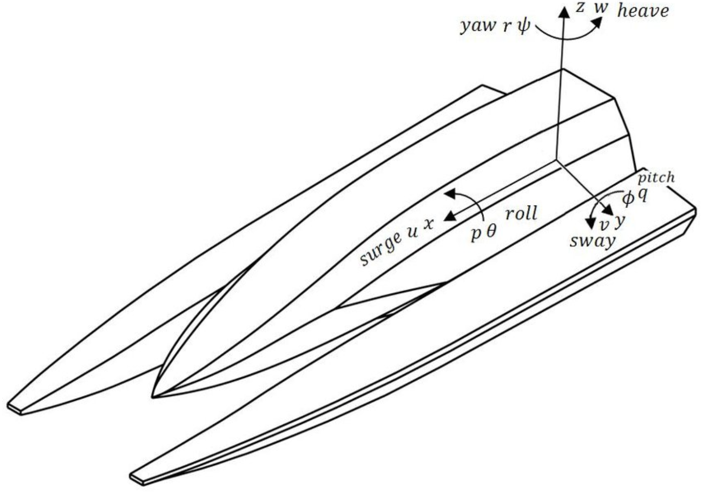

Wind always comes from the right side of the vessel, true wind angle will always be negative because as the wind "opens" from the bow, it follows the negative direction (think right hand rule).

% coordinate system vectors [x y z]:
boat_force_vector = [0 0 0]; % [N]
boat_torque_vector = [0 0 0]; % [Nm]
boat_reaction = [boat_force_vector; boat_torque_vector];

% boat generated variables
boat_speed = 0.01; % [m/s] initialized to non zero for calculation
boat_heel = -0.01; % [rad] initialized to non zero for calculation

Import Airfoil Data

naca18 = csvread("xf-naca0018-il-Re-500k-200k-100k-Main.csv",1,0);
% sample call: [cl, cd, cdp, cm] = findAirfoilCoeff(500000, 9, naca18)

## Sail

S_span = 2; % sail height [m]
S_avg_ch = 1; % average chord of sail [m]
S_alpha = 10; % sail angle of attack [deg]
S_mass = 10; % sail mass [kg]
S_airfoil = naca18;
sailMedium = SailMedium(rho_air, mu_air, naca18);

## Hull

Assumed resistance curve:

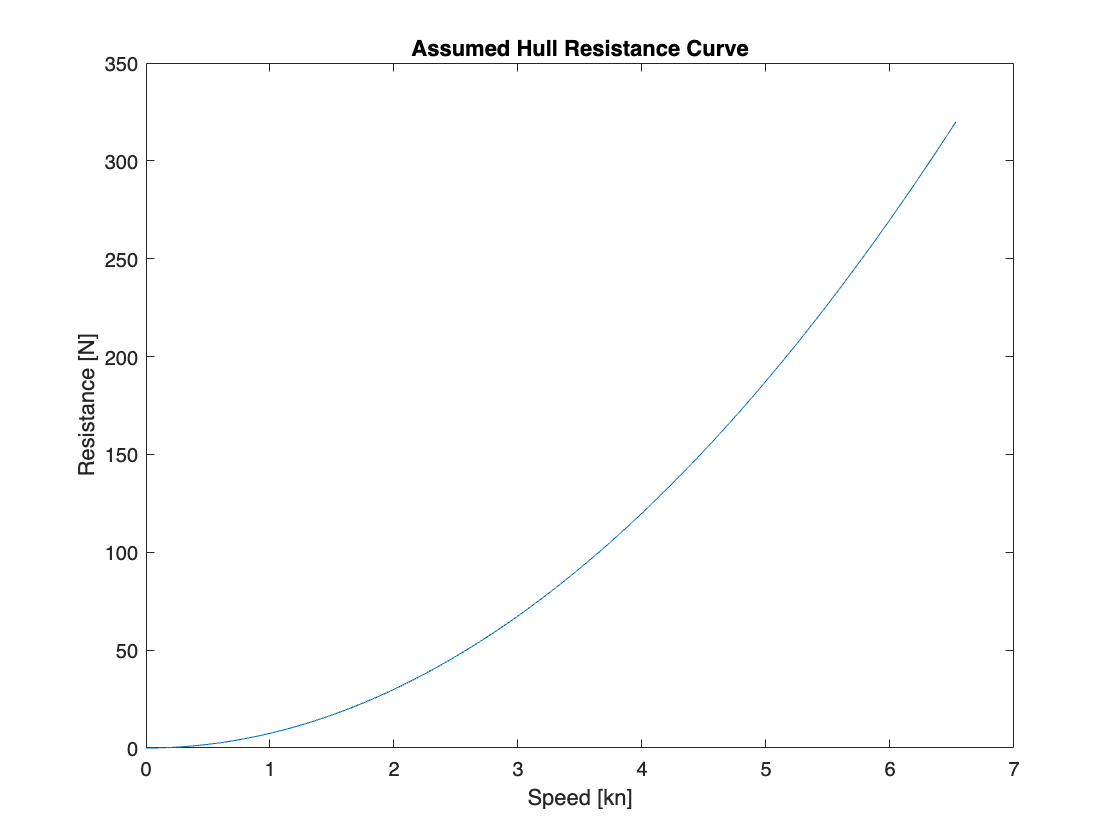

H_par = 7.5; % hull drag parameter
H_length = 2.35; %LOA [m]
froude_n = 0.7; % defined planing limit
boat_max_speed_kn = froude_n*sqrt(H_length*9.81) * ms_to_kn;% max hull speed [kn]
boat_speeds_kn=0:0.01:boat_max_speed_kn; % [kn]
H_resistance = H_par.*boat_speeds_kn.^2; % [N]
figure;
plot(boat_speeds_kn, H_resistance)
title('Assumed Hull Resistance Curve');
xlabel('Speed [kn]');
ylabel('Resistance [N]');

## Keel

K_span = 1; % Keel length [m]
K_avg_ch = 0.3; % keel average chord [m]
K_alpha = 0; %[rad] keel angle of attack
K_mass = 60; % Keel weight [kg]
K_airfoil = naca18;
keelMedium = KeelMedium(rho_water, mu_water, naca18);

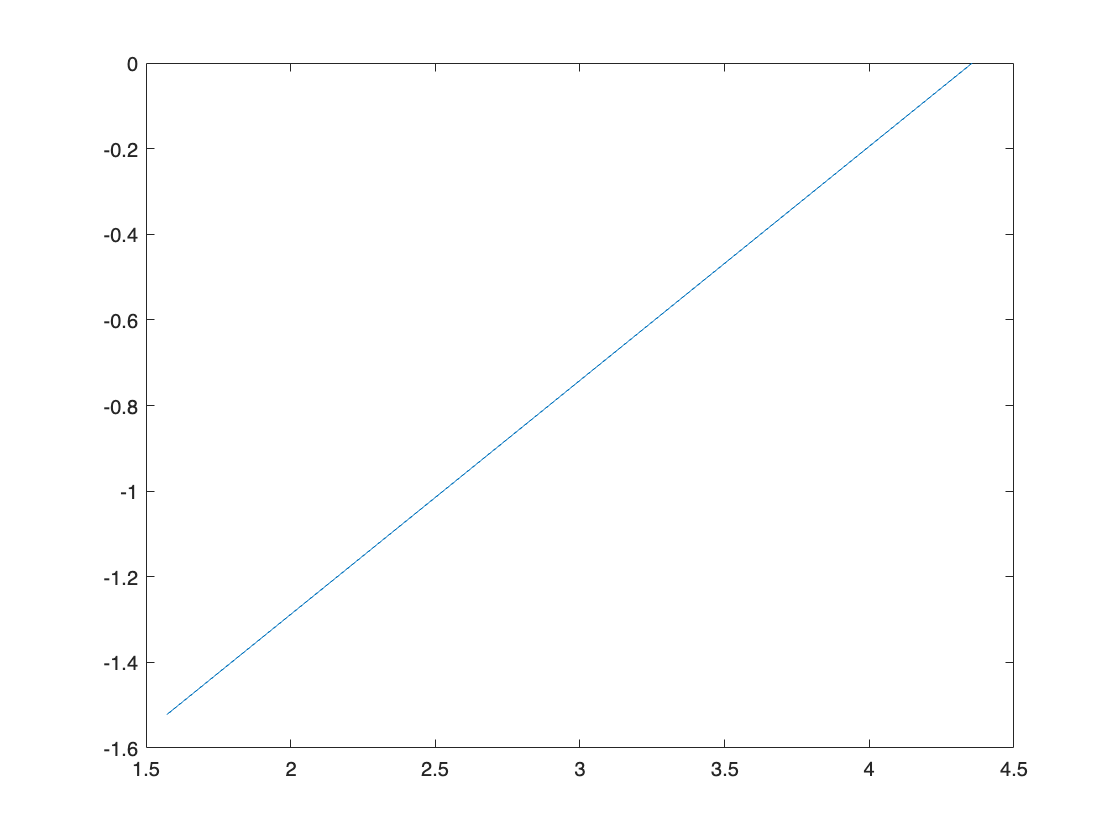

difference = 0;
old_boat_heel = 0;
i = 1;
boat_stats = [0 0];
W_speed = W_speed_kn(5)/ms_to_kn;
W_angle = deg2rad(-90);

while (difference < 0.001)

    [boat_reaction] = computeSailState(sailMedium, W_speed, W_angle, boat_reaction, boat_speed, boat_heel, S_span, S_avg_ch, S_alpha, S_mass, S_airfoil);
    [boat_speed] = hull(boat_reaction, H_par);
    [boat_reaction, boat_heel] = computeKeelState(keelMedium, W_speed, W_angle, boat_reaction, boat_speed, boat_heel, K_span, K_avg_ch, K_mass, K_airfoil);
    [boat_speed] = hull(boat_reaction, H_par);
    
    difference = boat_heel-old_boat_heel;
    old_boat_heel = boat_heel;

    boat_stats(i,:) = [boat_speed boat_heel];
    i = i + 1;

end

plot(boat_stats)

## Where is the worst heel angle?

Iterating through headdings to find worst heeling angle, at highwst wind speed

W_speed = W_speed_kn(5)/ms_to_kn;
sailMedium = SailMedium(rho_air, mu_air, S_airfoil, W_speed, S_area, S_avg_ch, S_alpha, S_span, S_mass);

for k = 1:size(W_heading,2)

    H_heading=deg2rad(W_heading(k));

    S_area_M=S_area;
    difference=1;
    while (difference > 0.0001) 
        % Compute
        [W_app_angle] = getApparentWind(W_speed, boat_speed, H_heading);
        [S_thrust,S_torque]=sailMedium.computeSailState(boat_heading, boat_heel);
        boat_force_vector(1) = S_thrust;
        boat_torque_vector(1) = -S_torque;
        [boat_heel_rad]=keel(boat_torque_vector(1), K_length, K_weight);
        [boat_speed]=hull(S_thrust, H_par);
        
        % Rectify Area
        old_S_area_M=S_area_M;
        S_area_M=S_area*cos(boat_heel_rad);

        % difference
        difference=abs(old_S_area_M-S_area_M);
    end
    H_heel_at_heading(k)=rad2deg(boat_heel_rad);
end

% plotting heel angle
figure;
hold on;
plot(W_heading, H_heel_at_heading)
yline(20);
yline(-20);
title('Finding Worst Heeling angle @ Hull Heading')
xlabel('Hull heading relative to true Wind [deg]')
ylabel('Hull Heel Angle [deg] (port=+ve)')

## Keel Study - Length

Here we investigate the variance of keel parameters on the performance. We choose a heading of 126deg (20deg of heel in the previous plot), and max wind speed (20kn)

% modifying keel values
var_factor = 0.25;
K_weightArr = (K_weight-K_weight*0.1):20:(K_weight+K_weight*0.1)
K_lengthArr = (K_length-K_length*var_factor):0.01:(K_length+K_length*var_factor);
% setting environmental const
W_speed = W_speed_kn(5)/1.94384;
H_heading=deg2rad(100);

for j = 1:size(K_weightArr,2)
    for k = 1:size(K_lengthArr,2)
        S_area_M=S_area;
        difference=1;
        while (difference > 0.0001) 
            % Compute
            [boat_heading] = getApparentWind(W_speed, boat_speed, H_heading);
            [S_thrust,S_torque, sail_heeling_force_wind,S_angle]=sail(rho_air, mu_air, naca18, W_speed, boat_heading, S_area_M, S_avg_ch, S_alpha, S_span, S_mass, boat_heel_rad);
            [boat_heel_rad]=keel(S_torque, K_length, K_weight, sail_heeling_force_wind, boat_heel_rad);
            [boat_speed]=hull(S_thrust, H_par);
            
            % Rectify Area
            old_S_area_M=S_area_M;
            S_area_M=S_area*cos(boat_heel_rad);
    
            % difference
            difference=abs(old_S_area_M-S_area_M);
        end
        H_speeds_at_keel(j,k)=boat_speed*ms_to_kn;
        H_heel_deg_at_keel(j,k)=rad2deg(boat_heel_rad);
    end 
end

figure;
% find half of domain
half_of_x_domain=fix(size(K_lengthArr,2)/2);
yyaxis left
plot(K_lengthArr, H_speeds_at_keel(1,:));
ylabel('Hull Speed [kn]')
text(K_lengthArr(1,half_of_x_domain),H_speeds_at_keel(1,half_of_x_domain),'\leftarrow' + string(K_weightArr(1)) + 'Kg')
yyaxis right
plot(K_lengthArr, H_heel_deg_at_keel(1,:));
ylabel('Hull Heel Angle [deg]')
title('Keel Study')
xlabel('Keel Length [m]')
hold on
for w = 2:size(H_speeds_at_keel,1)
    yyaxis left
    plot(K_lengthArr, H_speeds_at_keel(w,:));
    text(K_lengthArr(1,half_of_x_domain),H_speeds_at_keel(w,half_of_x_domain),'\leftarrow' + string(K_weightArr(w)) + 'Kg')
    yyaxis right
    plot(K_lengthArr, H_heel_deg_at_keel(w,:));
end
hold off

## Polar Plot

Interation to find boat speed based on wind speed and heading relative to wind

% Wind Speed
for w = 1:size(W_speed_kn,1)

    W_speed = W_speed_kn(w)/1.94384;
    
    % Heading Respect to True Wind
    for k = 1:size(W_heading,2)

        H_heading=deg2rad(W_heading(k));

        S_area_M=S_area;
        difference=1;
        while (difference > 0.0001) 
            % Compute
            [boat_heading] = getApparentWind(W_speed, boat_speed, H_heading);
            [S_thrust,S_torque, sail_heeling_force_wind,S_angle]=sail(rho_air, mu_air, naca18, W_speed, boat_heading, S_area_M, S_avg_ch, S_alpha, S_span, S_mass, boat_heel_rad);
            [boat_heel_rad]=keel(S_torque, K_length, K_weight, sail_heeling_force_wind, boat_heel_rad);
            [boat_speed]=hull(S_thrust, H_par);
            
            % Rectify Area
            old_S_area_M=S_area_M;
            S_area_M=S_area*cos(boat_heel_rad);
    
            % difference
            difference=abs(old_S_area_M-S_area_M);
        end
        speed_polar(k,w) = boat_speed*ms_to_kn;
    end
end
% plotting polar speed
figure;
color_array=['c'; 'b'; 'g'; 'y'; 'r'];
label_array=num2str(W_speed_kn);
label_array=label_array + "kn";
speed_polar_temp=transpose(speed_polar(:,1));
H_heading_temp=deg2rad(W_heading);
polarplot(H_heading_temp,speed_polar_temp,color_array(1))
title('Hull Speed [kn] @ Hull Headings [deg] and Wind Speeds [kn]');
text(W_heading(1),speed_polar(1,1),label_array(1,:));
hold on;
for w = 2:size(speed_polar,2)
    speed_polar_temp=transpose(speed_polar(:,w));
    H_heading_temp=deg2rad(W_heading);
    polarplot(H_heading_temp,speed_polar_temp,color_array(w))
    text(W_heading(1),speed_polar(1,w),label_array(w,:));
end
maximum = max(max(speed_polar_temp));
[x,y]=find(speed_polar==maximum);
fprintf('Optimal Sailing Heading: %g deg',W_heading(1,x))

## Print Variables

fprintf(...
    'Sail angle of attack: %g deg',S_alpha,...
    'Sail area: %g m2',S_area,...
    'Sail mass: %g kg',S_mass,...
    'Hull Max Speed: %g kn',boat_max_speed_kn,...
    'Keel weight: %g kg',K_weight,...
    'Keel length: %g m',K_length...
    )